clear
clc
close all

% t = 0:1:3600;
amp = 1.5;
% y = amp*sin(t/p);
% 
% d = diff(y);
% val = subs(d,x,pi/2);
% plot(t, y);

syms x t;
hold on
f = amp*sin(x);
disp(f);

$$\frac{3\,\sin\left(x\right)}{2}$$


d = diff(f,x);
disp(d);

$$\frac{3\,\cos\left(x\right)}{2}$$


g = atand(d);
disp(g);

$$\frac{180\,\mathrm{atan}\left(\frac{3\,\cos\left(x\right)}{2}\right)}{\pi }$$

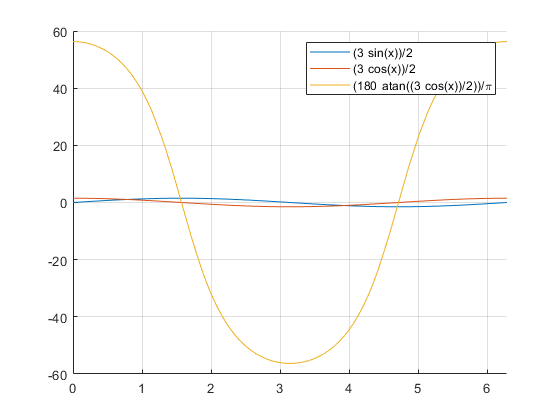




t = 0:.1:2*pi;
ang = double(subs(g, t));
disp = double(subs(f, t));


lims=[0 2*pi -60 60];
axis(lims)
legend("sin(x)", "dx/dt", "atan");
grid on

fplot(f);
fplot(d);
fplot(g);

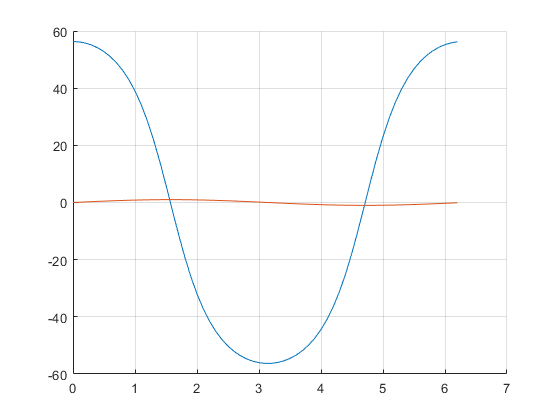


figure(2);
hold on
grid on
plot(t, (180/pi)*atan((3*cos(t))/2));
plot(t, sin(t));